# PRÁCTICA 3 - SESIÓN 2

# REDES NEURONALES

En este apartado se introduce la creación de una red neuronal artificial del tipo **perceptrón multicapa (MLP)** utilizando MATLAB. Se comienza con una arquitectura simple, formada por una única capa oculta con dos neuronas, con el objetivo de visualizar su estructura básica, explorar sus propiedades internas y familiarizarse con su funcionamiento inicial antes del entrenamiento.

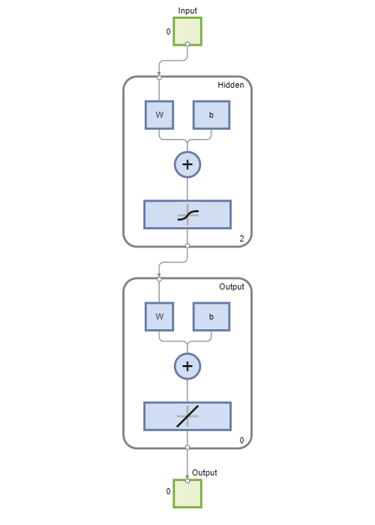

% Creamos una red neuronal MLP (perceptrón multicapa) con 2 neuronas en la capa oculta:
net = feedforwardnet(2);  % el argumento significa que hay 2 nodos en la capa oculta
% Visualizamos la estructura de la red neuronal:
view(net) % se muestra un esquema con las capas y nodos; el número debajo a la derecha de la capa indica cuántas neuronas tiene

% Mostramos todas las propiedades configurables de la red:
display(net)

net =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 2
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inputConne

## FUNCIÓN DE ACTIVACIÓN

Las funciones de activación son componentes fundamentales en una red neuronal, ya que introducen **no linealidad** en el modelo y permiten que **aprenda relaciones complejas entre entradas y salida**s. En este bloque se analiza gráficamente el comportamiento de la función **logsig**, y se justifica su elección para esta red. Además, se compara con otras posibles funciones que podrían emplearse dependiendo del tipo de problema.

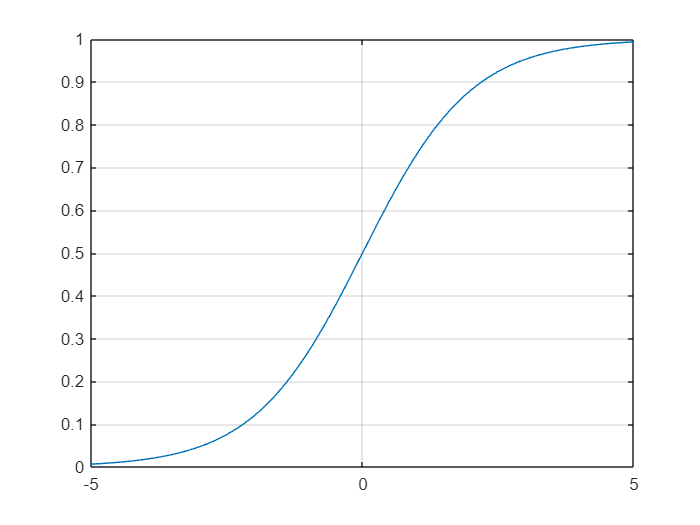

% Creamos un vector n de valores entre -5 y 5 para visualizar la función de activación:
n = -5:0.1:5;
a = logsig(n); % aplicamos la función sigmoidea logística (logsig)

% Representamos gráficamente la función logsig:
plot(n,a)
grid on

% Configuramos la función de activación de cada capa:
net.layers{1}.transferFcn='logsig';  % Capa oculta con función logsig
net.layers{2}.transferFcn='logsig';  % Capa de salida también con logsig

## RAZÓN DE ELECCIÓN DE `LOGSIG`

Se justifica la elección de la función `logsig` como función de activación, especialmente en la capa de salida, debido a que sus **salidas están en el rango [0,1]**, lo cual resulta apropiado para interpretar las salidas como **probabilidades**. En tareas como **clasificación binaria** o **reconocimiento de patrones** es habitual usar esta función en la capa de salida. También se comentan alternativas posibles como `tansig` (tangente hiperbólica), que produce salidas en el rango [-1,1], o la **función escalón**, para clasificación binaria.

## DATOS DE ENTRADA Y SALIDA

Antes de entrenar una red neuronal, es fundamental definir correctamente los datos de entrada (**características**) y los valores objetivo (**targets**). En este apartado se construye una pequeña base de datos artificial que simula un problema sencillo de **clasificación binaria**, sirviendo como caso base para experimentar con la red neuronal creada.

% Creamos una matriz con las entradas (2 características por individuo) y los targets:
input = [1 1 0 0; 1 0 1 0];  % 4 individuos (columnas), 2 características cada uno (filas)
target = [0 1 1 0];          % salida deseada para cada individuo

% Configuramos la red con estas dimensiones:
net = configure(net, input, target);  % Ajusta la arquitectura a la dimensión de los datos

## SIMULACIÓN SIN ENTRENAMIENTO

Para comprender el comportamiento inicial de la red, se realiza una simulación con los **pesos aleatorios** generados al configurar la red. Esta simulación permite observar que, **sin entrenamiento previo, la red no es capaz de aproximarse a las salidas deseadas**, lo que pone de manifiesto la **necesidad de un proceso de aprendizaje**.

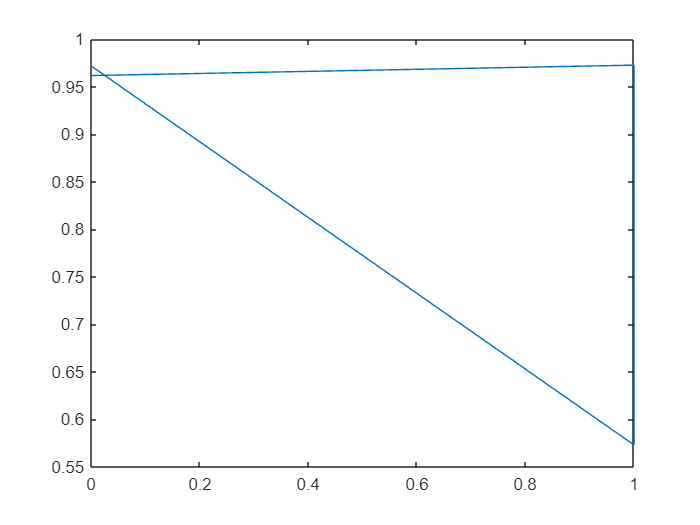

% Simulamos la salida de la red con pesos aleatorios (antes de entrenar):
output = sim(net, input);

% Representamos la salida obtenida frente a la deseada:
figure
plot(target, output) 

Como la red no ha sido entrenada, los resultados no coinciden con los valores deseados (target).

## INSPECCIÓN Y MODIFICACIÓN DE PESOS

Las redes neuronales se componen de **capas conectadas por pesos sinápticos**, los cuales determinan la salida de la red. En este apartado se inspeccionan los valores iniciales de los pesos y se realiza una modificación manual de uno de ellos, para observar su **influencia directa sobre las salidas de la red** antes del entrenamiento.

% Ver los pesos actuales de entrada:
net.IW{1,1}   % Pesos entre la capa de entrada y la capa oculta

ans =     2.2459   -3.2613
   -3.4893   -1.8721


% Ver los pesos actuales entre capa oculta y capa de salida:
net.LW{2,1}   % Pesos entre la capa oculta (capa 1) y la salida (capa 2)

ans =    -5.5989   -0.1098


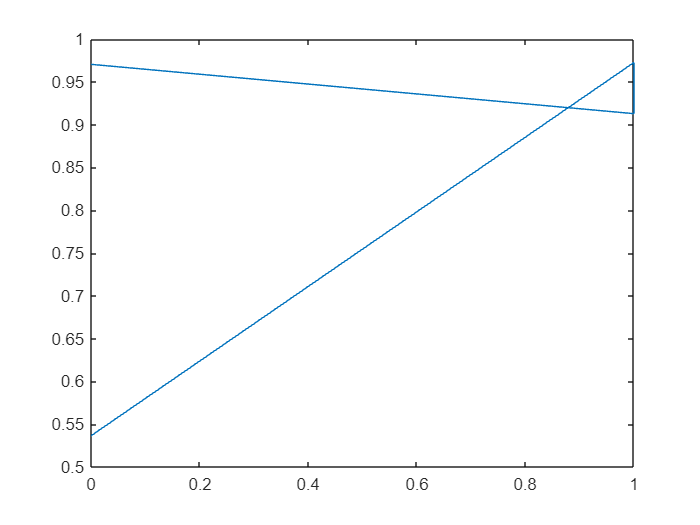

% Modificamos manualmente un peso específico:
net.IW{1,1}(1,2) = 5;  % Cambiamos el peso que conecta la 2ª entrada con la 1ª neurona oculta

% Simulamos de nuevo con el nuevo peso:
output = sim(net, input);

% Representamos la salida obtenida frente a la deseada:
figure
plot(target, output) 

Con esta modificación de pesos los resultados tampoco coinciden con los valores deseados (target).

## ENTRENAMIENTO DE LA RED

El entrenamiento es el proceso mediante el cual la red neuronal **ajusta sus pesos internos para minimizar el error** entre la salida obtenida y la deseada. Aquí se entrena la red con el conjunto de datos artificial, mostrando cómo mejora la salida tras el proceso de aprendizaje, y representando gráficamente los resultados.

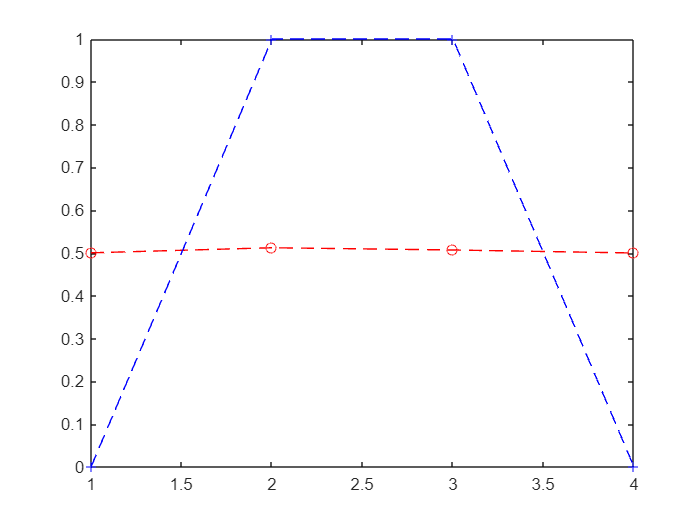

% Entrenamos la red con los datos de entrada y salida deseada:
net = train(net, input, target);

% Simulamos tras el entrenamiento:
output = sim(net, input);

% Representamos el resultado comparando salida obtenida y deseada:
t = 1:4;  % tiempo ficticio (1 a 4 muestras)
figure
plot(t, output, '--or', t, target, '--+b')

La salida (rojo) debe aproximarse a los valores deseados (azul) tras el entrenamiento

## PROBLEMA REAL CON REDES NEURONALES

Una vez comprendido el funcionamiento básico de una red neuronal, se aplica el modelo a un problema real: la clasificación de tumores de mama utilizando el conjunto de datos **Wisconsin Breast Cancer (WDBC)**. Este dataset proporciona un entorno más realista, con múltiples características y un número elevado de muestras, lo que permite evaluar la capacidad de generalización de la red en un contexto biomédico.

% Cargamos el dataset 'wdbc.data' del campus (cáncer de mama, Breast Cancer Wisconsin)
% Las etiquetas vienen codificadas como M = 1 (maligno), B = 0 (benigno)

% Eliminamos la columna de identificador (no aporta información útil):
bcdata = csvread('wdbc.data', 0, 1); % cargamos desde fila 0, columna 1 (saltamos la primera columna: ID)

% Comprobamos tamaño: 569 muestras, 30 características + 1 etiqueta
size(bcdata)  

ans =    569    31


% Extraemos el vector de salidas y la matriz de características:
target = bcdata(:,1);       % primera columna es la etiqueta (M/B codificado como 1/0)
indata = bcdata(:,2:31);    % las 30 características

% Transponemos para ajustarlo al formato que requiere la red (inputs = columnas)
target = target';
indata = indata';

## PREPROCESADO: NORMALIZACIÓN

Antes de entrenar la red con datos reales, es fundamental normalizar las entradas para asegurar una **convergencia más rápida y estable durante el aprendizaje**. En este paso se calcula el **rango de variación de cada característica** para establecer los **límites de entrada** en la red.

% Obtenemos los valores mínimos y máximos de cada característica:
input_ranges = minmax(indata)

input_ranges = 1.0e+03 *

    0.0070    0.0281
    0.0097    0.0393
    0.0438    0.1885
    0.1435    2.5010
    0.0001    0.0002
    0.0000    0.0003
         0    0.0004
         0    0.0002
    0.0001    0.0003
    0.0000    0.0001


## CREACIÓN Y CONFIGURACIÓN DE LA RED

Se construye una red neuronal más compleja, con una capa oculta de mayor tamaño, y se configuran los parámetros clave: funciones de activación y algoritmo de entrenamiento. Esta configuración se adapta a la naturaleza del problema de clasificación y al tamaño del conjunto de datos.

% Creamos una red MLP con 10 neuronas en la capa oculta:
net = feedforwardnet(10);

% Asignamos los rangos de entrada:
net.inputs{1}.range = input_ranges;

% Definimos funciones de activación:
net.layers{1}.transferFcn = 'tansig';  % capa oculta: tangente hiperbólica
net.layers{2}.transferFcn = 'logsig';  % capa de salida: logsig (salidas entre 0 y 1)

% Definimos el algoritmo de entrenamiento:
net.trainFcn = 'trainlm';  % algoritmo Levenberg-Marquardt, eficiente para redes pequeñas y medianas

## SEPARACIÓN ENTRE TRAIN Y TEST

Para **evaluar correctamente el rendimiento de la red**, se divide el conjunto de datos en dos subconjuntos: uno para entrenamiento y otro para test. Esta separación asegura que la red **no se evalúe sobre datos que ya ha visto**, permitiendo estimar su capacidad de **generalización a datos nuevos**.

% Dividimos el conjunto de datos: usamos las muestras impares para entrenamiento y las pares para test
% Recordatorio: las columnas representan las muestras (cada columna = un paciente)
training_in = indata(:,1:2:length(indata));         % columnas impares = entrenamiento
training_target = target(1:2:length(target));       % etiquetas correspondientes

testset.P = indata(:,2:2:length(indata));           % columnas pares = test
testset.T = target(2:2:length(target));             % etiquetas correspondientes

## ENTRENAMIENTO DE LA RED

La red neuronal se entrena exclusivamente con el subconjunto de entrenamiento. El proceso de aprendizaje **ajusta los pesos internos** utilizando el algoritmo Levenberg-Marquardt, **optimizando así la** **salida de la red para que se aproxime a las etiquetas reales** del conjunto de entrenamiento.

% Entrenamos la red con el conjunto de entrenamiento:
net = train(net, training_in, training_target);

## EVALUACIÓN DE LA RED EN EL CONJUNTO DE TEST

Tras el entrenamiento, se **evalúa el rendimiento de la red sobre el conjunto de test**. Para ello, se **compara la salida de la red con las etiquetas reales y se calcula la precisión** del modelo. Además, se **convierte la salida continua (entre 0 y 1) en etiquetas binarias** utilizando un **umbral**, permitiendo una interpretación más clara del resultado en términos de clasificación.

% Simulamos la red con los datos del conjunto de test:
output_test = sim(net, testset.P);

% Como las salidas son valores entre 0 y 1 (por la función logsig), se deben umbralizar para obtener una clase binaria:
output_test_bin = output_test > 0.5;  % si salida > 0.5 --> clase 1 (maligno), si no --> clase 0 (benigno)

% Calculamos la precisión (accuracy):
num_correct = sum(output_test_bin == testset.T);   % número de aciertos
precision = 100 * num_correct / length(testset.T); % porcentaje de aciertos
error = 100 - precision;                           % porcentaje de error

fprintf('Precisión sobre el conjunto de test: %.2f%%\n', precision);

Precisión sobre el conjunto de test: 38.73%


fprintf('Error sobre el conjunto de test: %.2f%%\n', error);

Error sobre el conjunto de test: 61.27%


## CONCLUSIÓN 

El desarrollo progresivo de este ejercicio ha permitido comprender el funcionamiento básico y avanzado de las redes neuronales artificiales, desde su construcción inicial con un conjunto de datos sintético hasta su aplicación en un problema real de clasificación médica. Se ha demostrado cómo la elección adecuada de funciones de activación, la normalización de datos y la configuración de la arquitectura afectan directamente al rendimiento del modelo. Además, se ha evidenciado la importancia de dividir los datos en subconjuntos de entrenamiento y test para evaluar la capacidad de generalización de la red. Por último, el uso de métricas como la precisión y el error ha facilitado la interpretación cuantitativa de los resultados. En conjunto, este ejercicio constituye una base sólida para el diseño y análisis de redes neuronales en aplicaciones biomédicas.